# Single Cam Stereo - Image Processing

### Split single camera stereo images

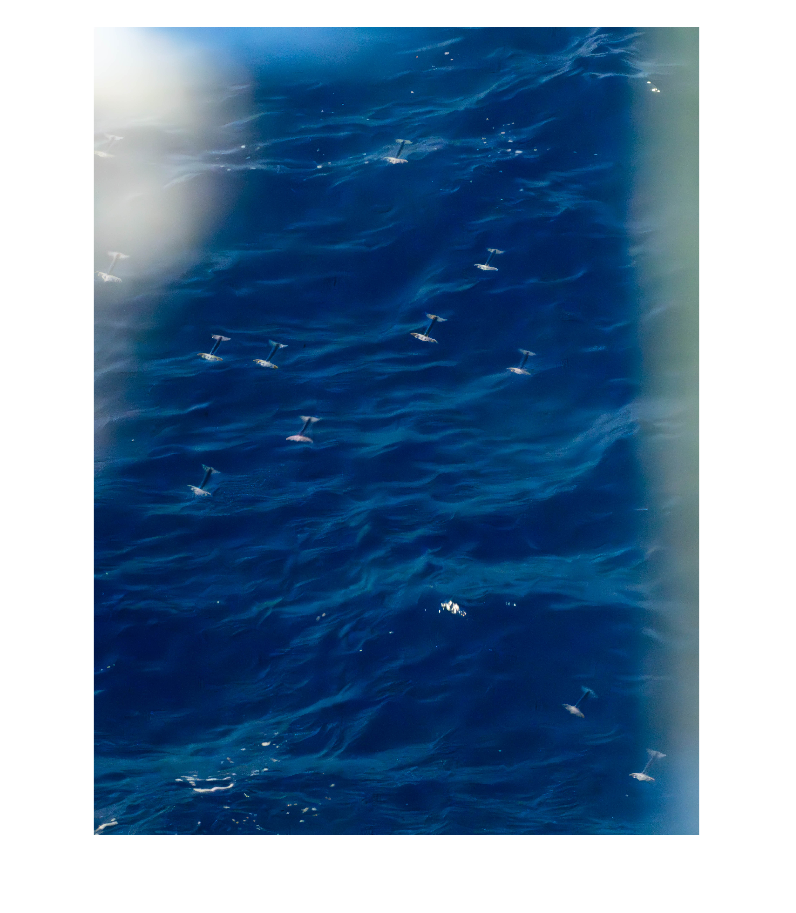

%import the image
tstImg = imread("C:\Users\yohan\OneDrive\Documents\Research Stuff\Squid Analysis\Nikon Data Analysis\Squid Sighting 6-12\Squid Data 6-12\Processed Images\Processed_6_12_images\DSC_1668.jpg");

%set the split line
splitLineVal = floor(0.5*size(tstImg,2));

%show the test image 
e1 = tstImg(:,1:splitLineVal,:);
imshow(e1);

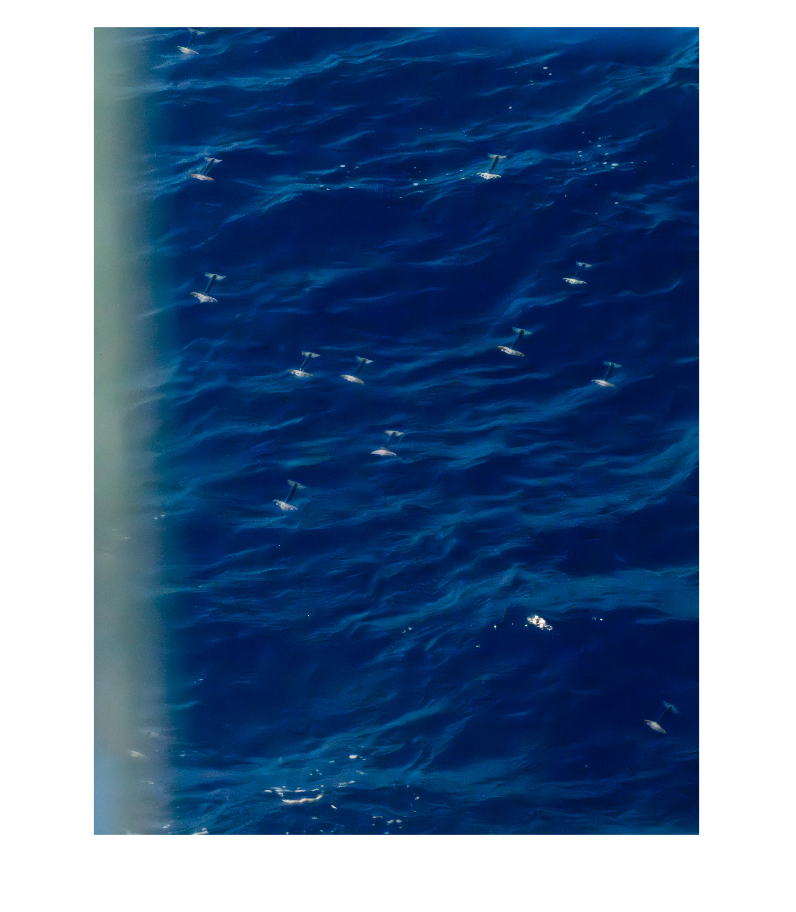

e2 = tstImg(:,splitLineVal:size(tstImg,2),:);
imshow(e2);

%set the source directory
srcDirectory = uigetdir;

%set the destination directories
cam1Imgs = uigetdir;
cam2Imgs = uigetdir;

%get the directory info
srcDirecInfo = dir(srcDirectory);

%for each image in the source directory
for i = 5:size(srcDirecInfo,1)
    if srcDirecInfo(i).isdir == 0
        %split it along the split line, and write the left and right halves to the
        %destination directory
        imToSplit = imread(fullfile(srcDirecInfo(i).folder,srcDirecInfo(i).name));

        %get the left and right halves
        leftImg = imToSplit(:,1:splitLineVal,:);
        rightImg = imToSplit(:,splitLineVal:size(imToSplit,2),:);

        %get the smaller image
        smallImg = size(leftImg,2) > size(rightImg,2);

        %store the smaller one in a larger image so that they are the same
        %size
        if smallImg 
            rightImg = [rightImg, zeros([size(rightImg,1), (size(leftImg,2) - size(rightImg,2)), 3])];
        else
            leftImg = [leftImg, zeros([size(rightImg,1), (size(rightImg,2) - size(leftImg,2)), 3])];
        end

        %save the images
        imwrite(leftImg,fullfile(cam1Imgs,srcDirecInfo(i).name + "_left.jpg"));
        imwrite(rightImg,fullfile(cam2Imgs,srcDirecInfo(i).name + "_right.jpg"))
    end
end

#### Load generated stereo parameters and compute object sizes

% %load("stereoParams_2_27_24.mat");
% 
% %select which image we want to use
% imgToCalib1 = imread("Cam 1\GOPR0188.JPG");
% imgToCalib2 = imread("Cam 2\GOPR5563.JPG");

% %select a start point in image 1
% imshow(imgToCalib1);
% im1Start = drawpoint;
% im1End = drawpoint;
% %get the point positions
% im1Points = [im1Start.Position;im1End.Position];

% %select the corrosponding start point in image 2
% imshow(imgToCalib2);
% im2Start = drawpoint;
% im2End = drawpoint;
% 
% %get the point positions
% im2Points = [im2Start.Position;im2End.Position];

% %compute the positions of each of the pairs of points
% pointPositions = triangulate(im1Points,im2Points,stereoParams)
% %get the distance between them to get the squid size
% sqdSize = abs(norm(pointPositions(1,:) - pointPositions(2,:)))
% %multiply by the checkerboard error (said it was 19 but it is actually
% %26.79mm)
% chkError = 26.79/19
% accSizeCalc = sqdSize*chkError
% stereoError = 370/accSizeCalc